In the following examples we plan on experimenting with complex impedances. We will explore how resistances, inductors and capacitors behave in an alternating current circuit, how they react regarding the components around them in situations with different source amplitudes and frequences. In order to work with alternating currents, we must first define the phasor representations of $u(t)
$ and $i(t)$.


$$\left.
\begin{array}{l}
u(t)=V_m\cos(\omega t+\theta )\\
i(t)=I_m\cos(\omega t+\varphi )\\
e^{j\rho }=\cos(\rho )+j\sin(\rho )
\end{array}
\right\}
\Rightarrow

\left.
\begin{array}{l}
u(t)=V_m\cos(\omega t+\theta )\\
i(t)=I_m\cos(\omega t+\varphi )\\
cos(\omega t+\theta )=Re\{e^{j(\omega t+\theta )}\}
\end{array}
\right\}
\Rightarrow

\left.
\begin{array}{l}
u(t)=V_mRe\{e^{j(\omega t+\theta )}\}\\
i(t)=I_mRe\{e^{j(\omega t+\varphi )}\}
\end{array}
\right\}
\Rightarrow


\begin{array}{l}
u(t)=Re\{V_me^{j\omega t}e^{j\theta}\}\\
i(t)=Re\{I_me^{j\omega t}e^{j\varphi}\}
\end{array}
$$


We define the phasor voltage $\widetilde{V}$as the complex representation of sinusoidal voltage $u(t)$, such that: $\widetilde{V}=V_me^{j\theta }$

We define the phasor current $\widetilde{I}$as the complex representation of sinusoidal voltage $i(t)$, such that:$\widetilde{I}=I_me^{j\varphi }$

This way we get:


$$\begin{array}{l}
u(t)=Re\{\widetilde{V}e^{j\omega t}\}\\
i(t)=Re\{\widetilde{I}e^{j\omega t}\}\\
\end{array}$$


We will be using these two equasions a lot later on.

Starting off simple, we have circuit number 1:

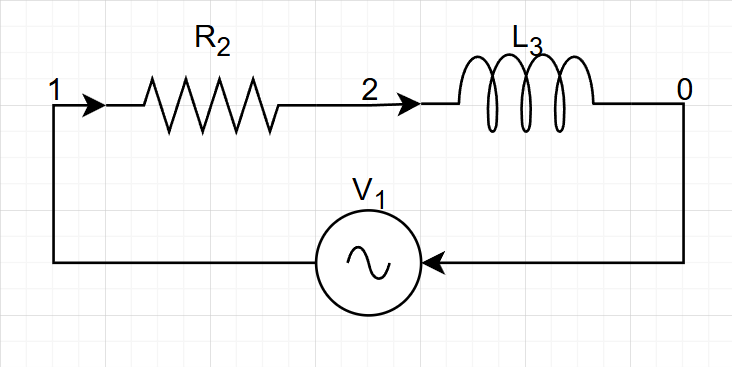

When working with aternating current sources, in circuits that house resistors and inductors, capacitors or both, it helps the analysis process to replace, wherever possible, said resistances and inductors by impedances. In practice what we do is we exchange two or more components of the circuit, with one. That allows us to have a single representitive value for the components in question while also keeping the behaviour of the circuit unchanged.

The reason this substitution works is because inductors and capacitors affect the current differently depending on the frequency and phase of the alternating current

Inductors oppose changes in current and cause the current to lag behind the voltage, while capacitors oppose changes in voltage and cause the current to lead the voltage.

Which means that they impede the flow of current in a predictable way, similar to what reisistors do, thats why it makes sense to combine them into one component.

In the circuit above we have a resistance and an inductor.

Τhe impedance of a resistor is given by the formula $Z_R=R$, here is the proof:


$$\left.
\begin{array}{l}
u(t)=i(t)R\\
u(t)=Re\{\widetilde{V}e^{j\omega t}\}\\
i(t)=Re\{\widetilde{I}e^{j\omega t}\}\\
\end{array}
\right\}
\Rightarrow

Re\{\widetilde{V}e^{j\omega t}\}=Re\{\widetilde{I}e^{j\omega t}\}R\Rightarrow\\

Re\{\widetilde{V}e^{j\omega t}\}=Re\{\widetilde{I}e^{j\omega t}R\}\Rightarrow\;\;

\widetilde{V}e^{j\omega t}={\widetilde{I}e^{j\omega t}R\Rightarrow\;\;

\widetilde{V}=R\widetilde{I}
$$
    

The impedance of a inductor is given by the formula $Z_L=j\omega L$, here is the proof:


$$\left.
\begin{array}{l}
u(t)=V_mcos(\omega t+ \phi)\\
V=L\frac{di}{dt}
\end{array}
\right\} \Rightarrow

di=\frac{V_m}{L}cos(\omega t + \phi)dt\Rightarrow i(t)=\frac{V_m}{L\omega}sin(\omega t + \phi)=\frac{V_m}{L\omega}cos(\omega t + \phi -\frac{\pi}{2})$$


So the complex voltage and current is:


$$V=V_me^{j(\omega t+\phi)}\\
I=\frac{V_m}{L\omega}e^{j(\omega t+\phi-\frac{\pi}{2})}$$


To make the calculations easier we do:


$$I=\frac{V_m}{L\omega}e^{j(\omega t+\phi-\frac{\pi}{2})}\Rightarrow\\
I=\frac{V_m}{L\omega}cos(\omega t+\phi-\frac{\pi}{2})+j\frac{V_m}{L\omega}sin(\omega t+\phi-\frac{\pi}{2})\Rightarrow\\
I=\frac{V_m}{L\omega}sin(\omega t+\phi)-j\frac{V_m}{L\omega}cos(\omega t+\phi)\Rightarrow\\
I=-j(j\frac{V_m}{L\omega}sin(\omega t+\phi)+\frac{V_m}{L\omega}cos(\omega t+\phi))\Rightarrow\\
I=-j\frac{V_m}{L\omega}e^{j(\omega t+\phi )}
$$


FInally:


$$Z_L=\frac{V}{I}\Rightarrow\\ Z_L=\frac{V_me^{j(\omega t+\phi)}}{-j\frac{V_m}{L\omega}e^{j(\omega t+\phi )}}\Rightarrow\\
Z_L=\frac{L\omega}{-j}=j\omega L$$


where $L$, is the iductance and $\omega $ is the angular frequency of the current that runs through the inductor. That gives us the value of the impedance that can replace said components $Z_{23}=Z_R+Z_L$, the circuit becomes:

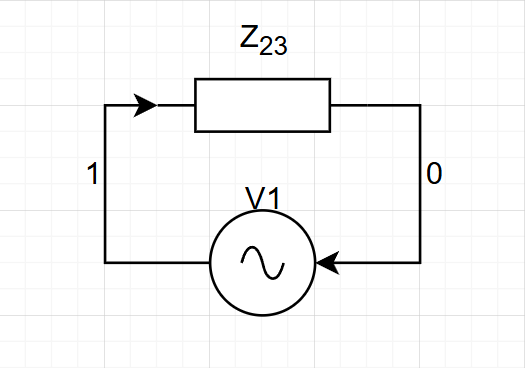

You can even see that the circuit looks much simpler, thats because it is.

With circuit now in this form the characteristic equasion becomes: $\widetilde{V}=Z_{23}\widetilde{I}$

What is intresting with inductors in alternating current circuits is how they impede the current flow in relation to the frequency of the source. Since in general inductors oppose changes in current we can imagine that the faster the current alternates, the more the inductor impedes its flow. We can visualize this by plotting the magnitude of the phasor current as a function of the source frequency:


$$\widetilde{I}(\omega )=\frac{\widetilde{V}}{R+j\omega L}$$


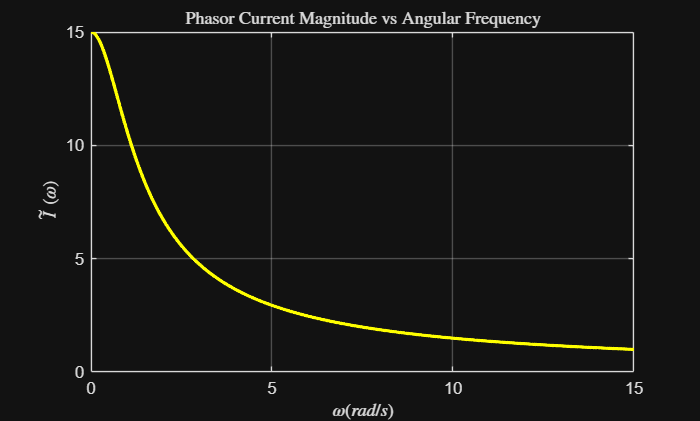

% Parameters
V =15; R =1; L =1;

% Frequency range (rad/s)
omega = linspace(0, 15, 1000);   % angular frequency (rad/s)
rev_omega = 1 ./ omega;

% Impedance
Z = R + 1j * omega * L;

% Current phasor
I = V ./ Z;

% Power Output
Pz = I*V;

% Plot
figure;
plot(omega, abs(I), 'y', 'LineWidth', 2);
xlabel('$\omega (rad/s)$','Interpreter','latex');
ylabel('$\widetilde{I}(\omega)$','Interpreter','latex');
title('Phasor Current Magnitude vs Angular Frequency','Interpreter','latex');
grid on;

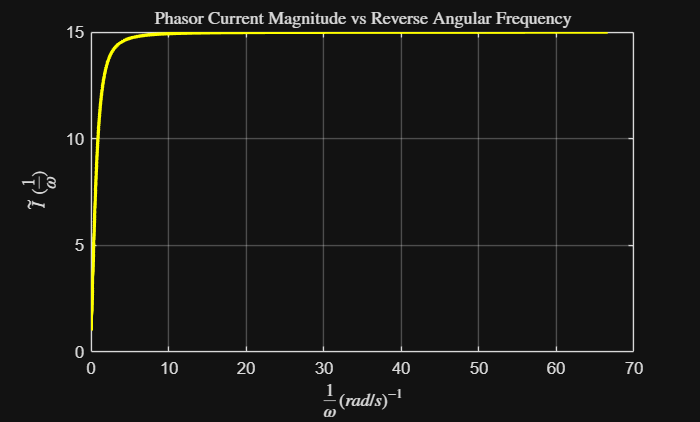

% Plot
figure;
plot(rev_omega, abs(I), 'y', 'LineWidth', 2);
xlabel('$\frac{1}{\omega} (rad/s)^{-1}$','Interpreter','latex');
ylabel('$\widetilde{I}(\frac{1}{\omega})$','Interpreter','latex');
title('Phasor Current Magnitude vs Reverse Angular Frequency','Interpreter','latex');
grid on;

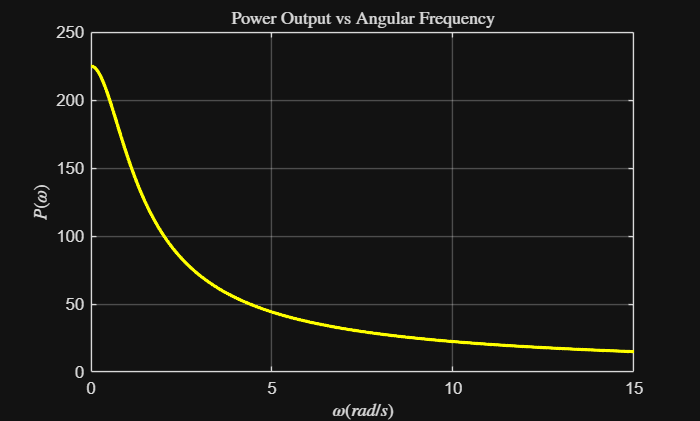

% Plot R/L
figure;
plot(omega, abs(Pz), 'y', 'LineWidth', 2);
xlabel('$\omega (rad/s)$','Interpreter','latex');
ylabel('$P(\omega)$','Interpreter','latex');
title('Power Output vs Angular Frequency','Interpreter','latex');
grid on;

Moving on, to circuit number 2:

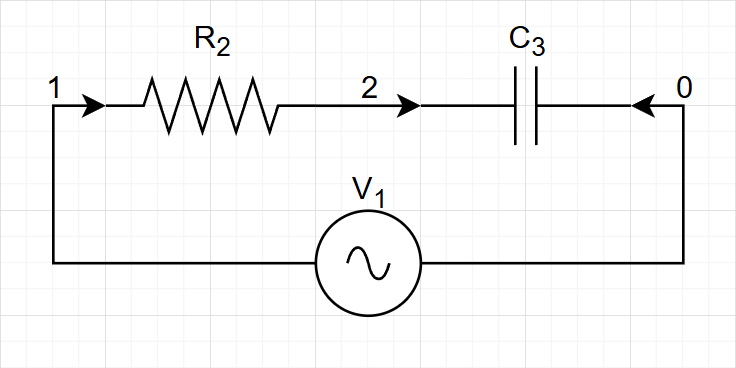

The impedance of a resistor is still given by: $Z_R=R$

The impedance of a capacitor is given by the formula $Z_C=\frac{1}{j\omega C}$, here is the proof:


$$\left.
\begin{array}{l}
u(t)=V_mcos(\omega t+ \phi)\\
I=C\frac{du}{dt}
\end{array}
\right\} \Rightarrow

I=C\frac{d(V_mcos(\omega t + \phi))}{dt}\Rightarrow I=-V_mC\omega sin(\omega t + \phi)\Rightarrow I=V_mC\omega cos(\omega t + \phi + \frac{\pi}{2})$$


So the complex voltage and current is:


$$u(t)=V_me^{j(\omega t+\phi)}\\
i(t)=V_mC\omega e^{i(\omega t+\phi+\frac{\pi}{2})}$$


To make the calculations easier we do:


$$i(t)=V_mC\omega e^{i(\omega t+\phi+\frac{\pi}{2})}\Rightarrow\\ 

i(t)=V_mC\omega cos(\omega t+\phi+\frac{\pi}{2})+jV_mC\omega sin(\omega t+\phi+\frac{\pi}{2})\Rightarrow\\

i(t)=-V_mC\omega sin(\omega t+\phi)+jV_mC\omega cos(\omega t+\phi)\Rightarrow\\

i(t)=j(jV_mC\omega sin(\omega t+\phi)+V_mC\omega cos(\omega t+\phi))\Rightarrow\\

i(t)=j V_mC\omega e^{j(\omega t+\phi)}$$


FInally:


$$Z_C=\frac{V}{I}\Rightarrow

Z_C=\frac{V_me^{j(\omega t+\phi)}}{j V_mC\omega e^{j(\omega t+\phi)}}\Rightarrow\\

Z_C=\frac{1}{j\omega C}$$


where $C$, is the capacity and $\omega $ is the angular frequency of the current that runs through the capacitor. That gives us the value of the impedance that can replace said components $Z_{23}=Z_R+Z_C$, the circuit becomes:

Again the circuit has become much simpler than initially.

With circuit now in this form the characteristic equasion becomes: $\widetilde{V}=Z_{23}\widetilde{I}$

Contrary to inductors capacitors resist changes in voltage by storing and supplying current, which means that the faster the voltage alternates the more the capacitor provides current. We can again visualise this by plotting the magnitude of the phasor current as a function of the source frequency:


$$\widetilde{I}(\omega)=(\frac{j\omega C}{j\omega CR+1})\widetilde{V}$$


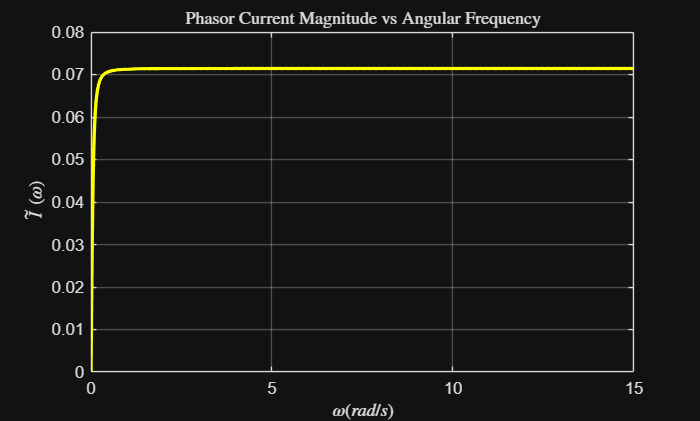

% Parameters
V =1; R =14; C =1;

% Frequency range (rad/s)
omega = linspace(0, 15, 1000);   % angular frequency (rad/s)
rev_omega = 1 ./ omega;


% Impedance
Z = (1j * omega * C) ./ (R * 1j * omega * C + 1);

% Current phasor
I = V * Z;

% Power Output
Pz = I*V;

% Plot
figure;
plot(omega, abs(I), 'y', 'LineWidth', 2);
xlabel('$\omega (rad/s$)','Interpreter','latex');
ylabel('$\widetilde{I}(\omega)$','Interpreter','latex');
title('Phasor Current Magnitude vs Angular Frequency','Interpreter','latex');
grid on;

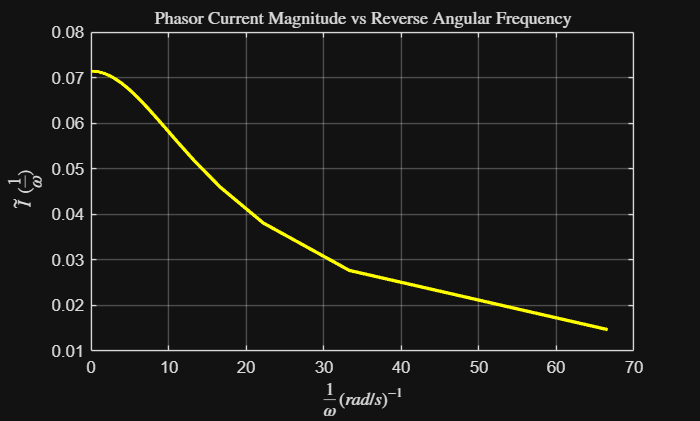

% Plot
figure;
plot(rev_omega, abs(I), 'y', 'LineWidth', 2);
xlabel('$\frac{1}{\omega} (rad/s)^{-1}$','Interpreter','latex');
ylabel('$\widetilde{I}(\frac{1}{\omega})$','Interpreter','latex');
title('Phasor Current Magnitude vs Reverse Angular Frequency','Interpreter','latex');
grid on;

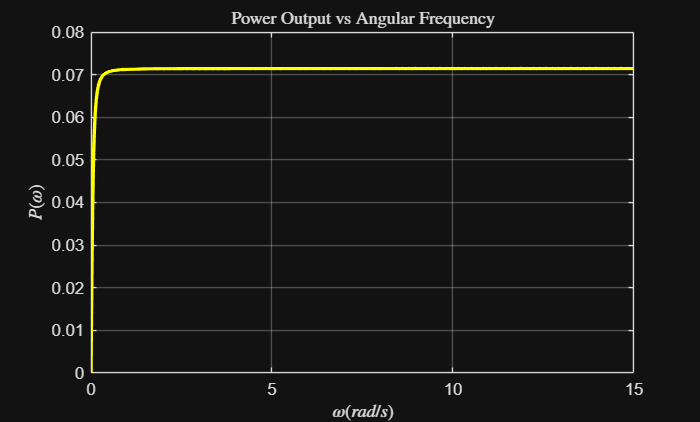

% Plot CR
figure;
plot(omega, abs(Pz), 'y', 'LineWidth', 2);
xlabel('$\omega (rad/s)$','Interpreter','latex');
ylabel('$P(\omega)$','Interpreter','latex');
title('Power Output vs Angular Frequency','Interpreter','latex');
grid on;

Up next, consisder this circuit:

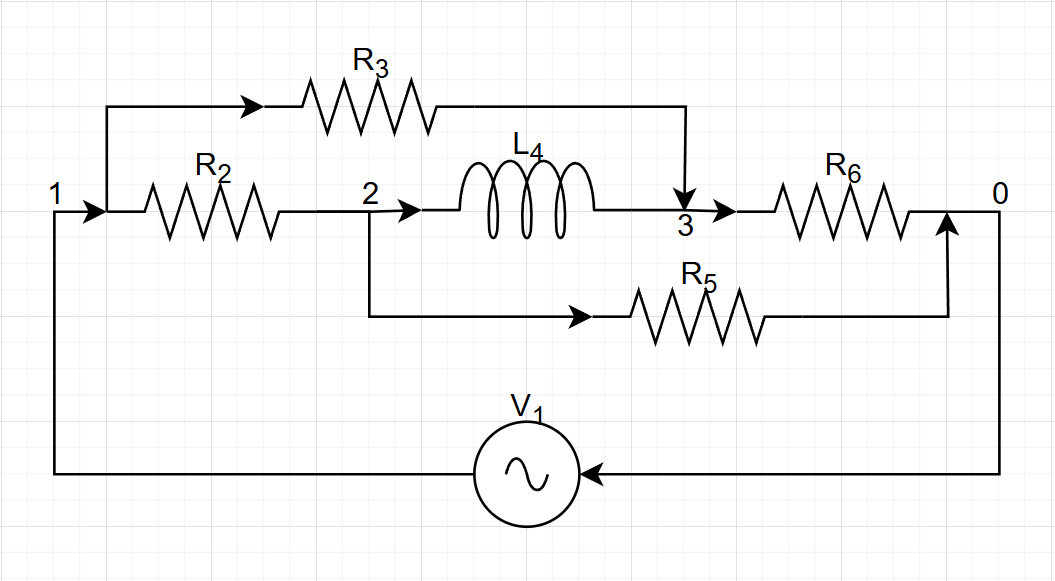

This is a modified Wheatstone Bridge circuit, modified to house an inductor in the middle instead of a resistor. Even though we are going to avoid assigning values to the resistances of this circuit, we assume$\frac{Z_3}{Z_6}\neq\frac{Z_2}{Z_5}$ in other words the bridge is unbalanced, since current not flowing through $L_4$ defeats the whole point. We will be analysing the circuit symbolically. To analyse the circuit we will replace each of the components with an impedance since we cant combine any two components into one, due to the way the circuit is constructed.

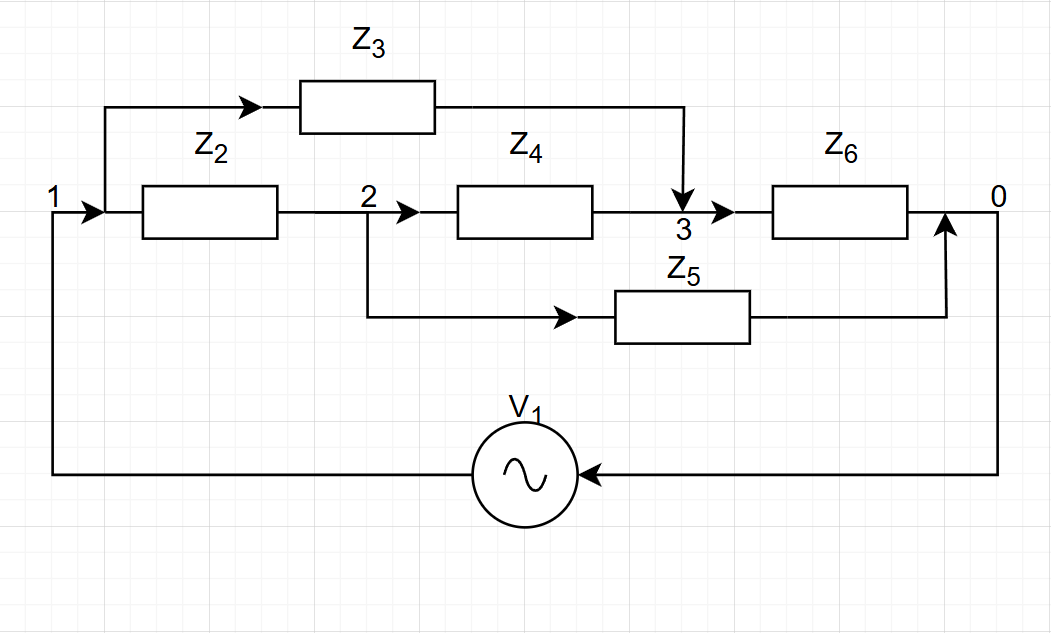

Where: $Z_2=R_2,\;
Z_3=R_3,\;
Z_4=j\omega L_4,\;
Z_5=R_5,\;
Z_6=R_6$

While the source now is: $V_1=\widetilde{V}=V_me^{j\theta}$

We get the current equasions from Kirhoff's Current Law:


$$\left.
\begin{array}{l}
i_2=i_4+i_5\\
i_3+i_4=i_6\\
\end{array}
\right\}
\Rightarrow

\left.
\begin{array}{l}
\frac{v_1-v_2}{Z_2}=\frac{v_2-v_3}{Z_4}+\frac{v_2-v_0}{Z_5}\\
\frac{v_1-v_3}{Z_3}+\frac{v_2-v_3}{Z_4}=\frac{v_3-v_0}{Z_6}\\
\end{array}
\right\}
\Rightarrow

\left.
\begin{array}{l}
\frac{v_1-v_2}{Z_2}=\frac{v_2-v_3}{Z_4}+\frac{v_2}{Z_5}\\
\frac{v_1-v_3}{Z_3}+\frac{v_2-v_3}{Z_4}=\frac{v_3}{Z_6}\\
\end{array}
\right\}
\Rightarrow

\begin{array}{l}
(\frac{1}{Z_2})v_1-(\frac{1}{Z_2}+\frac{1}{Z_4}+\frac{1}{Z_5})v_2+(\frac{1}{Z_4})v_3=0\\
(\frac{1}{Z_3})v_1+(\frac{1}{Z_4})v_2-(\frac{1}{Z_3}+\frac{1}{Z_4}+\frac{1}{Z_6})v_3=0\\
\end{array}

$$


We know that $v_0=0$, the impedances are known, and so we solve $v_2,\;v_3$. We will rewrite the system in matrix form:

syms V2 V3 V1 Z2 Z3 Z4 Z5 Z6

% KCL at node 2
eq1 = (V2 - V1)/Z2 + (V2 - V3)/Z4 + V2/Z5 == 0;

% KCL at node 3
eq2 = (V3 - V1)/Z3 + (V3 - V2)/Z4 + V3/Z6 == 0;

% Solve the system
sol = solve([eq1, eq2], [V2, V3]);

% Access solutions
V2_sol = sol.V2;
V3_sol = sol.V3;

disp('Value of V2:');

Value of V2:


disp(V2_sol);

$$\frac{V_{1}\,Z_{5}\,\left(Z_{3}\,Z_{4}+Z_{2}\,Z_{6}+Z_{3}\,Z_{6}+Z_{4}\,Z_{6}\right)}{Z_{2}\,Z_{3}\,Z_{4}+Z_{2}\,Z_{3}\,Z_{5}+Z_{2}\,Z_{3}\,Z_{6}+Z_{2}\,Z_{4}\,Z_{6}+Z_{3}\,Z_{4}\,Z_{5}+Z_{2}\,Z_{5}\,Z_{6}+Z_{3}\,Z_{5}\,Z_{6}+Z_{4}\,Z_{5}\,Z_{6}}$$

disp('Value of V3:');

Value of V3:


disp(V3_sol);

$$\frac{V_{1}\,Z_{6}\,\left(Z_{2}\,Z_{4}+Z_{2}\,Z_{5}+Z_{3}\,Z_{5}+Z_{4}\,Z_{5}\right)}{Z_{2}\,Z_{3}\,Z_{4}+Z_{2}\,Z_{3}\,Z_{5}+Z_{2}\,Z_{3}\,Z_{6}+Z_{2}\,Z_{4}\,Z_{6}+Z_{3}\,Z_{4}\,Z_{5}+Z_{2}\,Z_{5}\,Z_{6}+Z_{3}\,Z_{5}\,Z_{6}+Z_{4}\,Z_{5}\,Z_{6}}$$

So the symbolic answers are:


$$v_1=V_1\\

v_2=\frac{V_1\,Z_{5}\,\left(Z_{3}\,Z_{4}+Z_{2}\,Z_{6}+Z_{3}\,Z_{6}+Z_{4}\,Z_{6}\right)}{Z_{2}\,Z_{3}\,Z_{4}+Z_{2}\,Z_{3}\,Z_{5}+Z_{2}\,Z_{3}\,Z_{6}+Z_{2}\,Z_{4}\,Z_{6}+Z_{3}\,Z_{4}\,Z_{5}+Z_{2}\,Z_{5}\,Z_{6}+Z_{3}\,Z_{5}\,Z_{6}+Z_{4}\,Z_{5}\,Z_{6}}\\

v_3=\frac{V_1\,Z_{6}\,\left(Z_{2}\,Z_{4}+Z_{2}\,Z_{5}+Z_{3}\,Z_{5}+Z_{4}\,Z_{5}\right)}{Z_{2}\,Z_{3}\,Z_{4}+Z_{2}\,Z_{3}\,Z_{5}+Z_{2}\,Z_{3}\,Z_{6}+Z_{2}\,Z_{4}\,Z_{6}+Z_{3}\,Z_{4}\,Z_{5}+Z_{2}\,Z_{5}\,Z_{6}+Z_{3}\,Z_{5}\,Z_{6}+Z_{4}\,Z_{5}\,Z_{6}}\\

v_0=0$$


With these values we are now able to calculate the current in every branch, so the circuit is now solved. One intresting thing we can do with these results is check the Wheatstone Bridge principle, in other words if we take $v_2=v_3$ we should expect $i_4$ to be 0.

syms Z2 Z3 Z4 Z5 Z6
% Define the equation
eq = Z5*(Z3*Z4 + Z2*Z6 + Z3*Z6 + Z4*Z6) == Z6*(Z2*Z4 + Z2*Z5 + Z3*Z5 + Z4*Z5);

% Solve the equation for Z5
sol_Z5 = solve(eq, Z5);

% Compute Z5 / Z6
Z5Z6_ratio = simplify(sol_Z5 / Z6);

% Display the result
disp('Solving v2 = v3, for Z5/Z6, we get:');

Solving v2 = v3, for Z5/Z6, we get:


disp(Z5Z6_ratio);

$$\frac{Z_{2}}{Z_{3}}$$

We can already see that, $v_2=v_3\Rightarrow\frac{Z_5}{Z_6}=\frac{Z_2}{Z_3}$ which means that the bridge is balanced and that $i_4=0$ :


$$\left.
\begin{array}{l}
i_4=\frac{v_2-v_3}{Z_4}\\
v_2=v_3
\end{array}
\right\}
\Rightarrow

i_4=0$$


The following plot shows what happens to the current that runs the inductor when frequency is increased:


$$i_4(\omega)=\frac{v_2-v_3}{Z_4}=

\frac{V_1\,(Z_{5}\,\left(Z_{3}\,Z_{4}+Z_{2}\,Z_{6}+Z_{3}\,Z_{6}+Z_{4}\,Z_{6}\right)-Z_{6}\,\left(Z_{2}\,Z_{4}+Z_{2}\,Z_{5}+Z_{3}\,Z_{5}+Z_{4}\,Z_{5}\right))}{Z_4(Z_{2}\,Z_{3}\,Z_{4}+Z_{2}\,Z_{3}\,Z_{5}+Z_{2}\,Z_{3}\,Z_{6}+Z_{2}\,Z_{4}\,Z_{6}+Z_{3}\,Z_{4}\,Z_{5}+Z_{2}\,Z_{5}\,Z_{6}+Z_{3}\,Z_{5}\,Z_{6}+Z_{4}\,Z_{5}\,Z_{6})}=

\frac{V_1Z_4\,(Z_5Z_3-Z_6Z_2)}{Z_4(Z_2Z_3(Z_4+Z_5+Z+6)+Z_5Z_6(Z_2+Z_3+Z_4)+Z_4(Z_2Z_6+Z_3Z_5))}
$$



$$i_4(\omega)=\frac{V_1\,(Z_5Z_3-Z_6Z_2)}{Z_2Z_3(j\omega L+Z_5+Z+6)+Z_5Z_6(Z_2+Z_3+j\omega L)+j\omega L(Z_2Z_6+Z_3Z_5)}$$


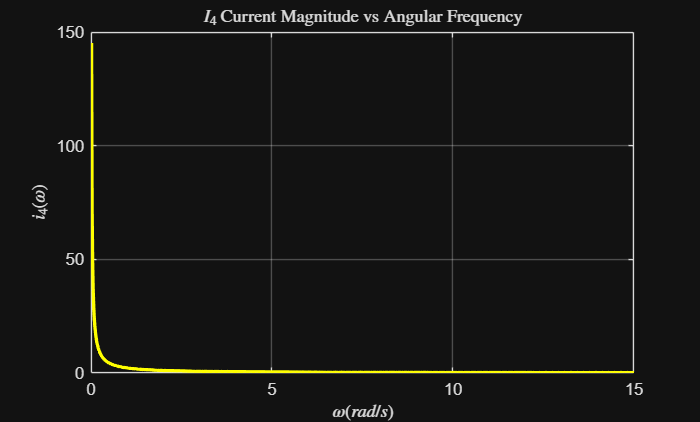

% Parameters
V1 =15;Z2 =14;Z3 =2;
L4 =1;Z5 =3;Z6 =1;
% Frequency range (rad/s)
omega = linspace(0, 15, 1000); 

% Inductor Impedance
Z4 = 1j*omega*L4;

% V2 Value

V2 = V1*Z5*(Z3*Z4+Z2*Z6+Z3*Z6+Z4*Z6)/(Z2*Z3*Z4+Z2*Z3*Z5+Z2*Z3*Z6+Z2*Z4*Z6+Z3*Z4*Z5+Z2*Z5*Z6+Z3*Z5*Z6+Z4*Z5*Z6);

% V3 Value
V3 = V1*Z6*(Z2*Z4+Z2*Z5+Z3*Z5+Z4*Z5)/(Z2*Z3*Z4+Z2*Z3*Z5+Z2*Z3*Z6+Z2*Z4*Z6+Z3*Z4*Z5+Z2*Z5*Z6+Z3*Z5*Z6+Z4*Z5*Z6);

% Current phasor
I = (V2-V3) ./ Z4;

% Plot 1
figure;
plot(omega, abs(I), 'y', 'LineWidth', 2);
xlabel('$\omega (rad/s)$','Interpreter','latex');
ylabel('$i_4(\omega)$','Interpreter','latex');
title('$I_4$ Current Magnitude vs Angular Frequency','Interpreter','latex');
grid on;

The following plot shows what happens to the current that runs the inductor as the bridge balance changes while value of $Z_5$ moves from $0$ to $30$:


$$i_4(\frac{Z_2}{Z_3}-\frac{Z_5}{Z_6})=\frac{V_1\,(Z_5Z_3-Z_6Z_2)}{(Z_2Z_3(Z_4+Z_5+Z_6)+Z_5Z_6(Z_2+Z_3+Z_4)+Z_4(Z_2Z_6+Z_3Z_5))}$$


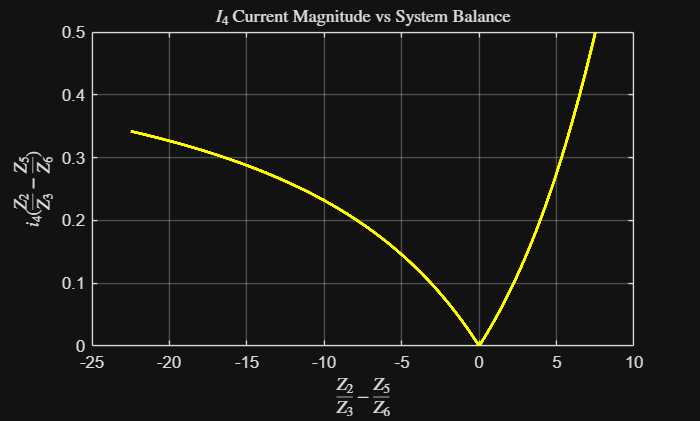

% Parameters
V1 =15;L4 =1;Z2 =15;
Z3 =2;Z6 =1;omega = 10;
Z5 = linspace( 0, 30, 10000);
% Balance range
balance = ((Z2/Z3)-(Z5./Z6));

% Inductor Impedance
Z4 = 1j*omega*L4;

% V2 Value

V2 = V1.*Z5.*(Z3.*Z4+Z2.*Z6+Z3.*Z6+Z4.*Z6)./(Z2.*Z3.*Z4+Z2.*Z3.*Z5+Z2.*Z3.*Z6+Z2.*Z4.*Z6+Z3.*Z4.*Z5+Z2.*Z5.*Z6+Z3.*Z5.*Z6+Z4.*Z5.*Z6);

% V3 Value
V3 = V1.*Z6.*(Z2.*Z4+Z2.*Z5+Z3.*Z5+Z4.*Z5)./(Z2.*Z3.*Z4+Z2.*Z3.*Z5+Z2.*Z3.*Z6+Z2.*Z4.*Z6+Z3.*Z4.*Z5+Z2.*Z5.*Z6+Z3.*Z5.*Z6+Z4.*Z5.*Z6);

% Current phasor
I = (V2-V3) ./ Z4;


% Plot 2
figure;
plot(balance, abs(I), 'y', 'LineWidth', 2);
xlabel('$\frac{Z_2}{Z_3} - \frac{Z_5}{Z_6}$','Interpreter','latex');
ylabel('$i_4(\frac{Z_2}{Z_3}-\frac{Z_5}{Z_6})$','Interpreter','latex');
title('$I_4$ Current Magnitude vs System Balance', 'Interpreter','latex');
grid on;